## Load Bbp data

bbp_dir = strcat(pwd, '/data');
cd(bbp_dir);
bbp_files = dir(fullfile(bbp_dir, 'bbp_*.csv'));

% Initialize an empty table
bbp_tbl = table();

% Loop through each file and append its contents
for i = 1:length(bbp_files)
    % Read the current CSV file
    tempTable = readtable(bbp_files(i).name);
    
    % Append to the combined table
    bbp_tbl = [bbp_tbl; tempTable]; % Concatenation
end

bbp_tbl = sortrows(bbp_tbl, 'date', 'ascend');
% Display the first 5 rows of the combined table
disp(bbp_tbl(1:min(5, height(bbp_tbl)), :));

            date            bbp_532nm      bbp_700nm 
    ____________________    __________    ___________

    01-Dec-2022 01:04:55    0.00075799     0.00011652
    01-Dec-2022 01:04:57    0.00090201     9.5774e-05
    01-Dec-2022 01:04:58    0.00061397     7.5026e-05
    01-Dec-2022 01:04:59      0.000854     0.00028251
    01-Dec-2022 01:05:00    0.00070998    -7.9674e-06



## Plot Bbp data

range_bbp = [0 0.03]

range_bbp =          0    0.0300


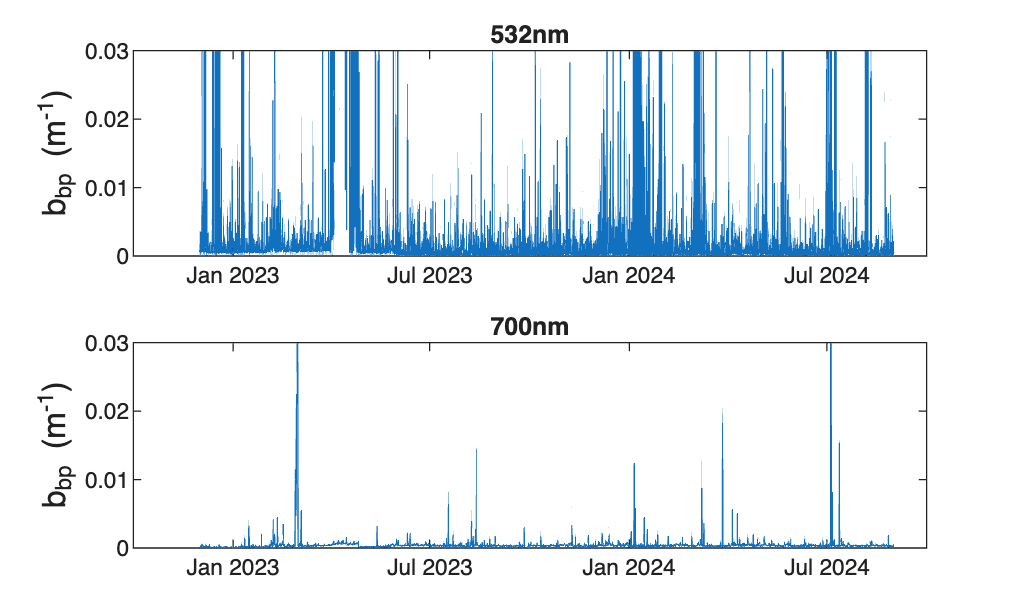


figure(1)
subplot(2,1,1)
    plot(bbp_tbl{:,1},bbp_tbl{:,2})
    title('532nm')
    ylabel('b_{bp} (m^{-1})','FontSize', 12)
    ylim(range_bbp) 
subplot(2,1,2)
    plot(bbp_tbl{:,1},bbp_tbl{:,3})
    title('700nm')
    ylabel('b_{bp} (m^{-1})','FontSize', 12)
    ylim(range_bbp) 

## Smooth data

% Smooth input data
day_window = 7

day_window = 7

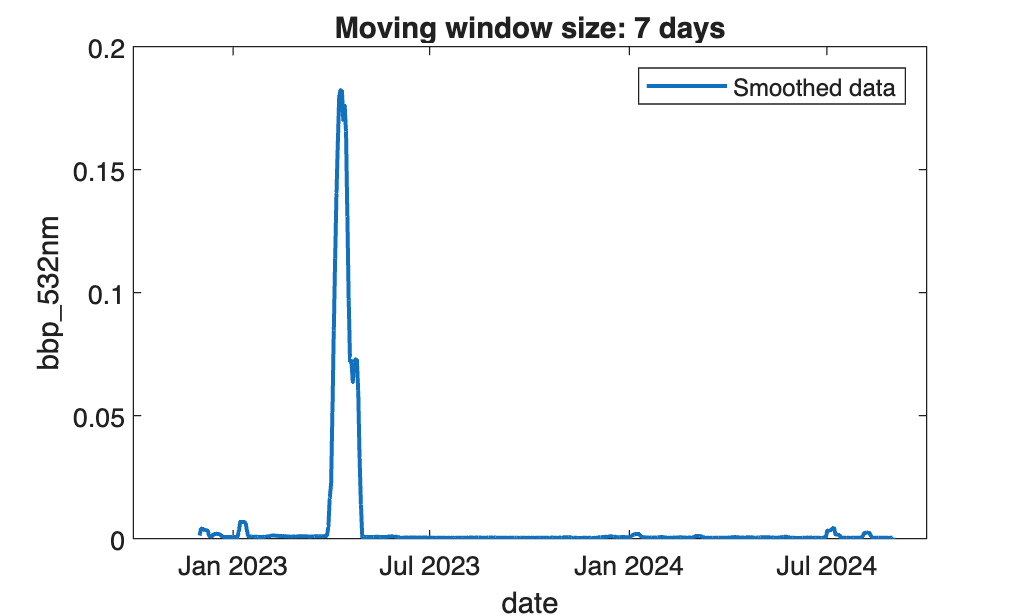

[smoothed532,winSize] = smoothdata(bbp_tbl(:,"bbp_532nm"),"movmean",days(day_window), ...
    SamplePoints=bbp_tbl.date);

% Display results
figure
plot(bbp_tbl.date,smoothed532.bbp_532nm,SeriesIndex=1,LineWidth=1.5, ...
    DisplayName="Smoothed data")
title("Moving window size: " + string(winSize));
legend
ylabel("bbp_532nm",Interpreter="none")
xlabel("date")

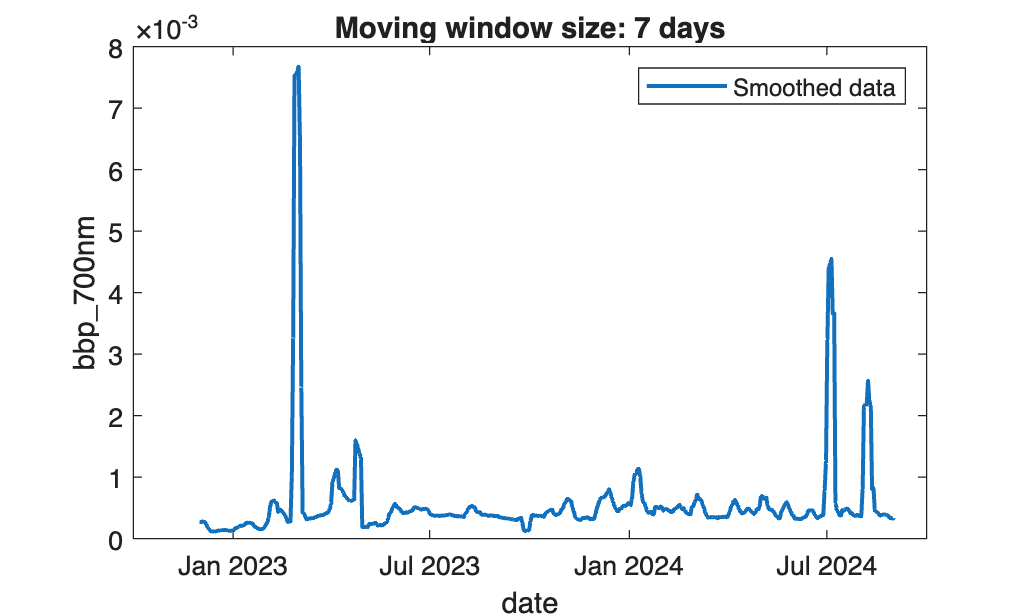


% Smooth input data
[smoothed700,winSize2] = smoothdata(bbp_tbl(:,"bbp_700nm"),"movmean",days(day_window), ...
    SamplePoints=bbp_tbl.date);

% Display results
figure
plot(bbp_tbl.date,smoothed700.bbp_700nm,SeriesIndex=1,LineWidth=1.5, ...
    DisplayName="Smoothed data")
title("Moving window size: " + string(winSize2));
legend
ylabel("bbp_700nm",Interpreter="none")
xlabel("date")

clear winSize2

## Load and filter sediment trap data

trap_flux_tbl = readtable('trap_flux.csv');


% Exclude rows in trap_flux_tbl with Date values < 12/01/0022
trap_flux_tbl(trap_flux_tbl.Mid_Date < datetime(2022, 12, 1), :) = [];

% Display the first 10 rows of the trap flux table
disp(trap_flux_tbl(1:min(10, height(trap_flux_tbl)), :));

    Cup    Duration       Date        Mid_Date     JulianDay    Mid_Julian    tot_mass_flux    org_c_flux    caco3_flux    opal_flux    terr_flux    nitro_flux
    ___    ________    __________    __________    _________    __________    _____________    __________    __________    _________    _________    __________

     1        14       2022-12-01    2022-12-08      5449          5456          77.143            2.53        14.763        4.092       51.963         0.35   
     2        14       2022-12-15    2022-12-22      5463          5470          17.714           1.002        

## Plot sediment trap data

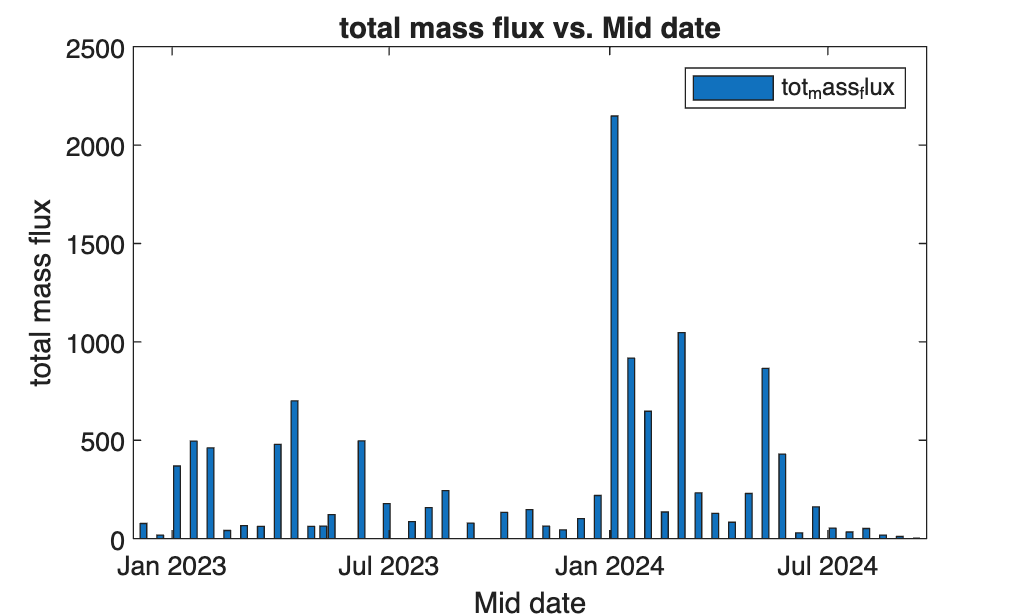

% Create bar of selected data
h = bar(trap_flux_tbl.Mid_Date,trap_flux_tbl.tot_mass_flux,"DisplayName","tot_mass_flux");

% Add xlabel, ylabel, title, and legend
xlabel("Mid date")
ylabel("total mass flux")
title("total mass flux vs. Mid date")
legend

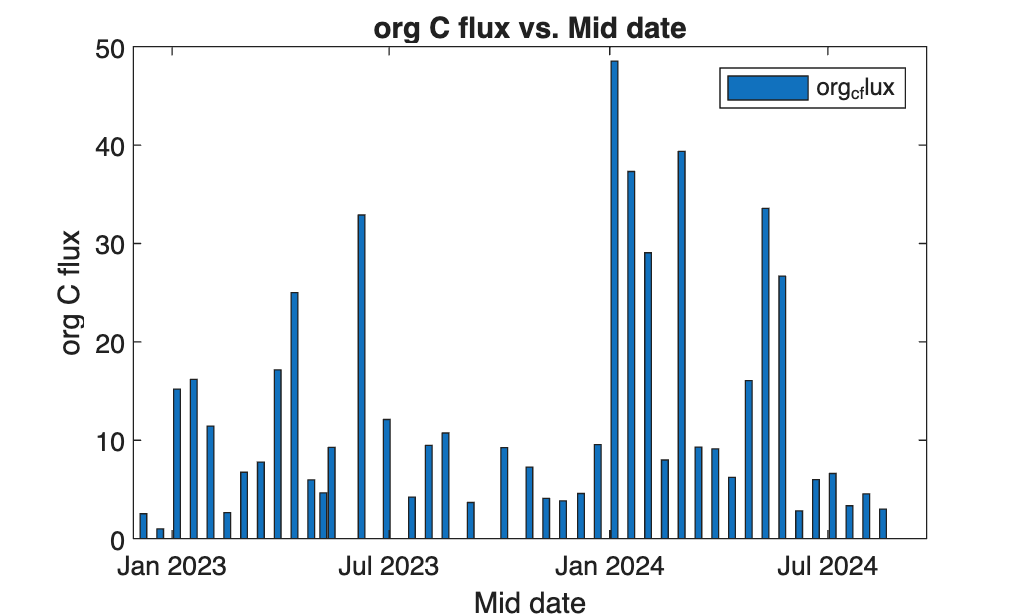


h2 = bar(trap_flux_tbl.Mid_Date,trap_flux_tbl.org_c_flux,"DisplayName","org_c_flux");

% Add xlabel, ylabel, title, and legend
xlabel("Mid date")
ylabel("org C flux")
title("org C flux vs. Mid date")
legend

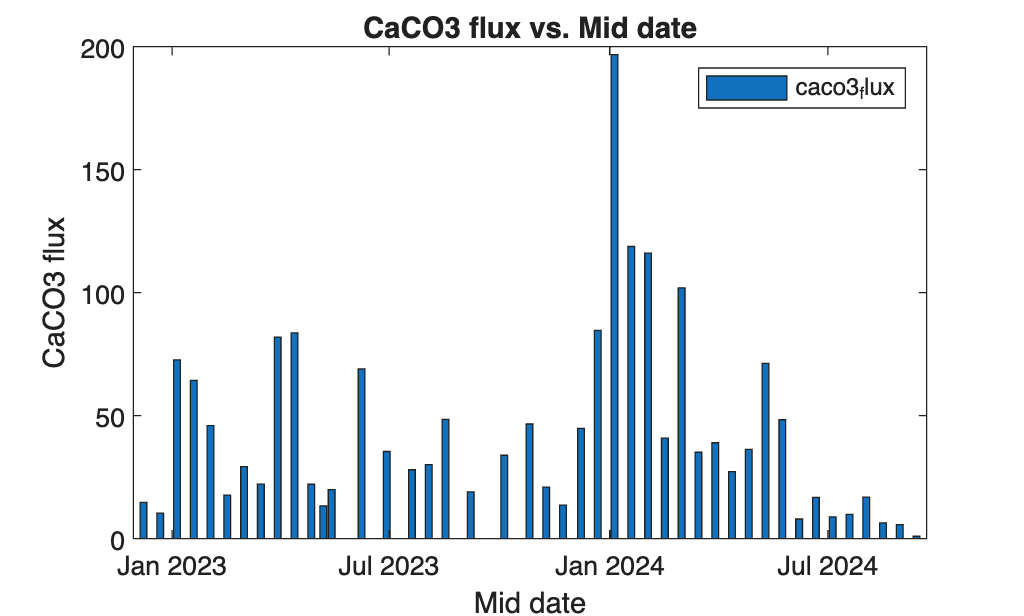


h3 = bar(trap_flux_tbl.Mid_Date,trap_flux_tbl.caco3_flux,"DisplayName","caco3_flux");

% Add xlabel, ylabel, title, and legend
xlabel("Mid date")
ylabel("CaCO3 flux")
title("CaCO3 flux vs. Mid date")
legend

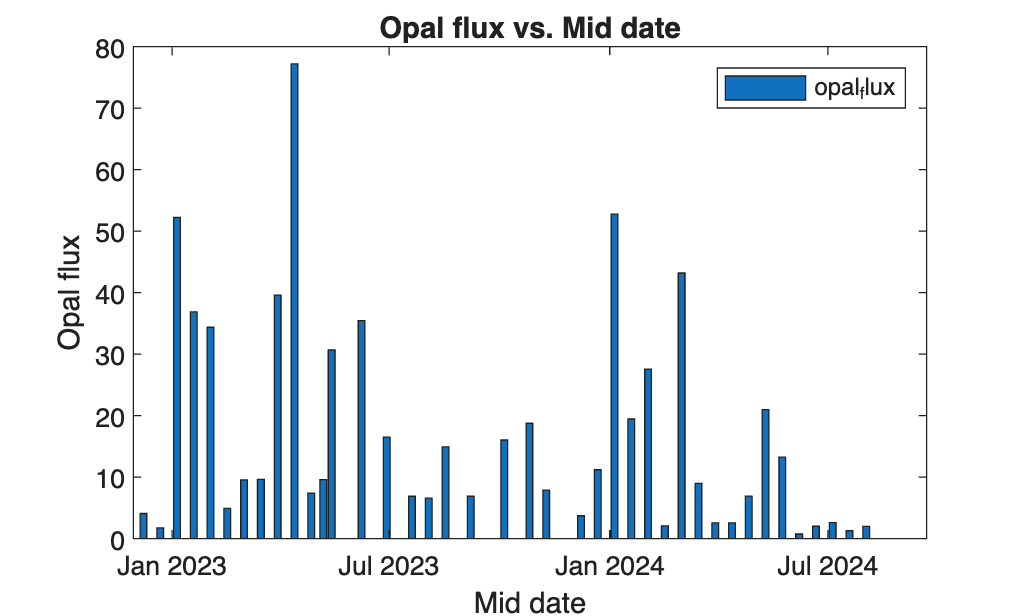


h4 = bar(trap_flux_tbl.Mid_Date,trap_flux_tbl.opal_flux,"DisplayName","opal_flux");

% Add xlabel, ylabel, title, and legend
xlabel("Mid date")
ylabel("Opal flux")
title("Opal flux vs. Mid date")
legend